fprintf('please Select an image');

please Select an image

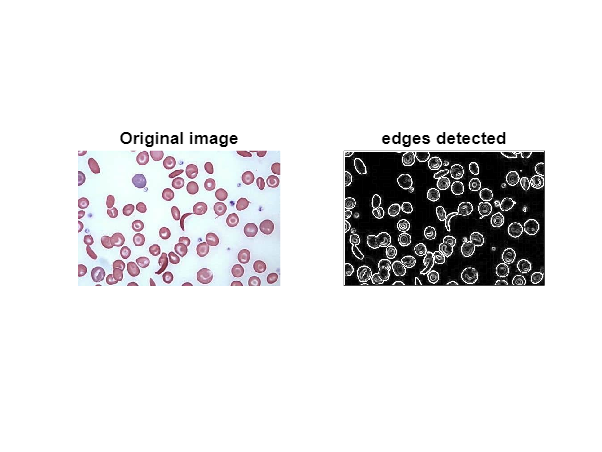

y=uigetfile('*.*');
i=imread(y);
J=rgb2gray(i);


K=padarray(J,[1,1],0);
K=double(K);
[rows,columns]=size(K);
L=zeros(rows,columns);
gx=[-1 -1 -1;0 0 0;1 1 1];
gy=[-1 0 1;-1 0 1;-1 0 1];
s1=[0 0 0;0 0 0;0 0 0];
s3=[0 0 0;0 0 0;0 0 0];
for r=2:rows-1
    for c=2:columns-1
      kernel=[K(r-1,c-1) K(r-1,c) K(r-1,c+1); K(r,c-1) K(r,c) K(r,c+1); K(r+1,c-1) K(r+1,c) K(r+1,c+1)];
      s1=kernel.*gx;
      s2=sum(s1,"all");
      s3=kernel.*gy;
      s4=sum(s3,"all");
      L(r,c)=sqrt(s2.^2+s4.^2);
    end
end
subplot(1,2,1);imshow(i);title("Original image");
subplot(1,2,2);imshow(uint8(L),[]);title('edges detected')